# Intro and references

## Nanocompartments proteins and promoters

### ΔVP1

There is no Uniprot reference exactly for this protein, here is the similar wild type protein:

[P49302 (VP1_POVMP)](https://www.uniprot.org/uniprotkb/P49302/entry)

Promoter used:

Gal1

### VP2C-GFP

[P12908 (VP2_POVMC)](https://www.uniprot.org/uniprotkb/P12908/entry)

Promoter used:

Gal10

## Constants references

Some of the constants were taken from the [SPARKLE project](https://2020.igem.org/Team:Estonia_TUIT/Model), supplementarty table 1.

# Model: constitutive gene expression

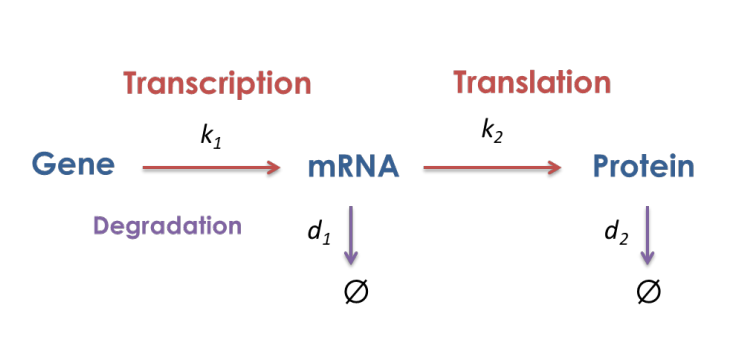

## Gal1

### Define model constants

p.CN = 1; % initial number of plasmids
% TODO: how to +- calculate it from the lab protocol?

p.d1 = 0.042116; % mRNA degradation rate
p.d2 = 0.02; % protein degradation rate
p.k2 = 1.4514; % translation rate
p.k1 = 10.22731087; % transcription rate

### Define simulation parameters

tfin = 60*6;
step = 0.1;
tspan = 0:step:tfin-step;

### Run the simulation

opti = odeset('AbsTol', 1e-8, 'RelTol', 1e-6);

Init = [0 0];

[t0, x0] = ode23t(@(t, x) model_const(t, x, p), tspan, Init, opti);

### Plot the results

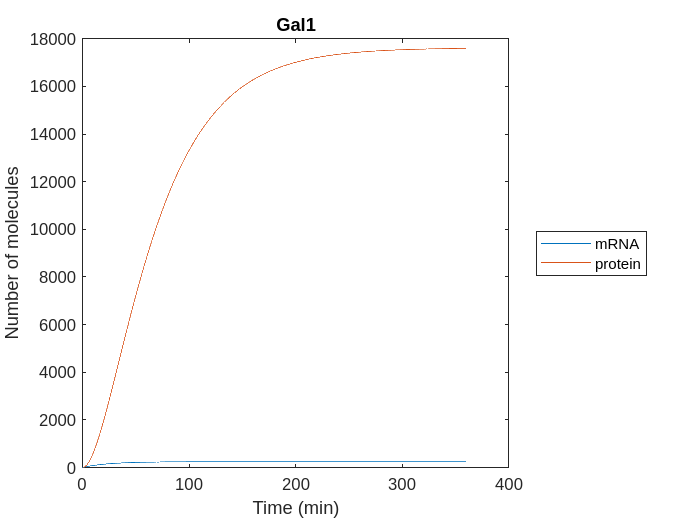

plot(t0, x0);
title('Gal1')
legend('mRNA', 'protein')
legend('location', 'eastoutside')
xlabel('Time (min)');
ylabel('Number of molecules')

## Gal10

WARNING: I just multiplied k2 and k1 by 10

### Define model constants

p.CN = 1; % initial number of plasmids
% TODO: how to +- calculate it from the lab protocol?

p.d1 = 0.042116; % mRNA degradation rate
p.d2 = 0.02; % protein degradation rate
p.k2 = p.k2 * 10; % translation rate
p.k1 = p.k1 * 10; % transcription rate

### Define simulation parameters

tfin = 60*6;
step = 0.1;
tspan = 0:step:tfin-step;

### Run the simulation

opti = odeset('AbsTol', 1e-8, 'RelTol', 1e-6);

Init = [0 0];

[t1, x1] = ode23t(@(t, x) model_const(t, x, p), tspan, Init, opti);

### Plot the results

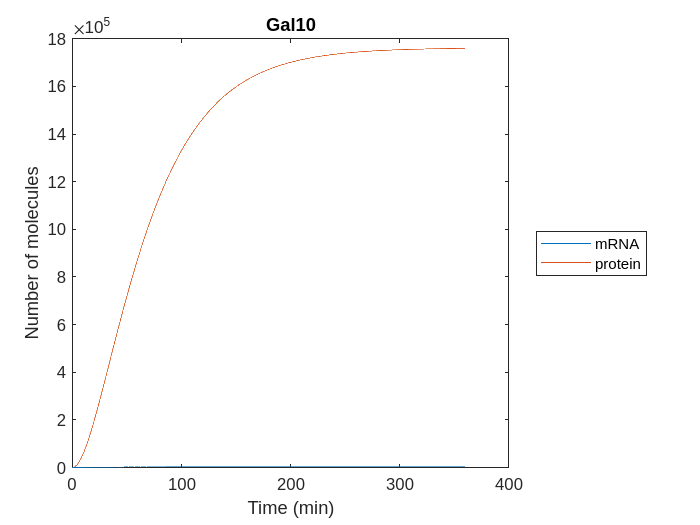

plot(t1, x1);
title('Gal10')
legend('mRNA', 'protein')
legend('location', 'eastoutside')
xlabel('Time (min)');
ylabel('Number of molecules')

### Plot Gal1 and Gal10 together

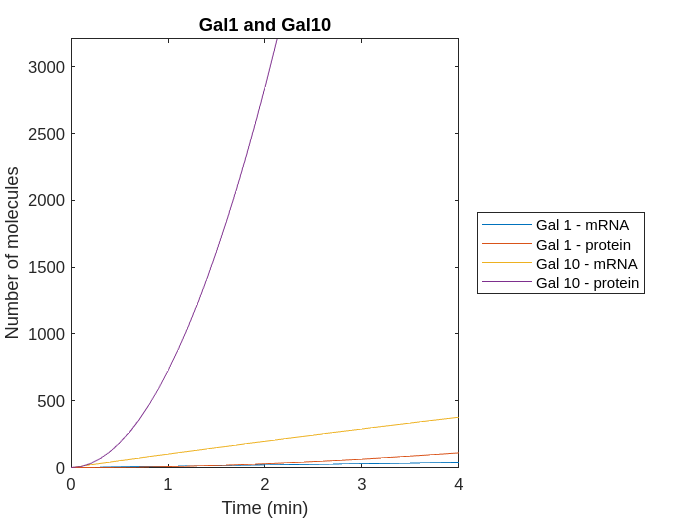

plot(t0, x0, t1, x1);
title('Gal1 and Gal10')

legend('Gal 1 - mRNA', 'Gal 1 - protein', 'Gal 10 - mRNA', 'Gal 10 - protein')
legend('location', 'eastoutside')

xlabel('Time (min)');
ylabel('Number of molecules')

xlim([0.00 4.00])
ylim([0 3211])

# Discussion

Model is quite adequate, but protein degradation constant is still neeeded (I couldn't find it). We can reverse engineer the only missing constant, using [aticle about nanocompartments](https://drive.google.com/file/d/1HGQm5Y4ci69OTvZ_6f9nJAm1Qh5OfvMR/view?usp=sharing) (actually, model is already close to the experimental data).

function [dxdt] = model_const(t, x, p)
    dxdt(1,1) = p.CN*p.k1-p.d1*x(1);
    dxdt(2,1) = p.k2*x(1)-p.d2*x(2);
end